# E2017

## Opgave 1

En diskret stokastisk variabel X kan antage værdierne: {0, 1, 2, 3, 4, 5} med følgende sandsynligheder:

a) Bestem sandsynligheden for at X har værdien 0: Pr(X=0).

Den samlede sandsynlighed er lig med 1.

Pr123 = 0.15*3; Pr4 = 0.25; Pr5 = 0.10;

Pr0 = 1 - Pr123 - Pr4 - Pr5

Pr0 =    2.0000e-01


b) Tegn graferne for pmf og cdf for den stokastiske variabel X

x = [0:1:5]

x =      0     1     2     3     4     5


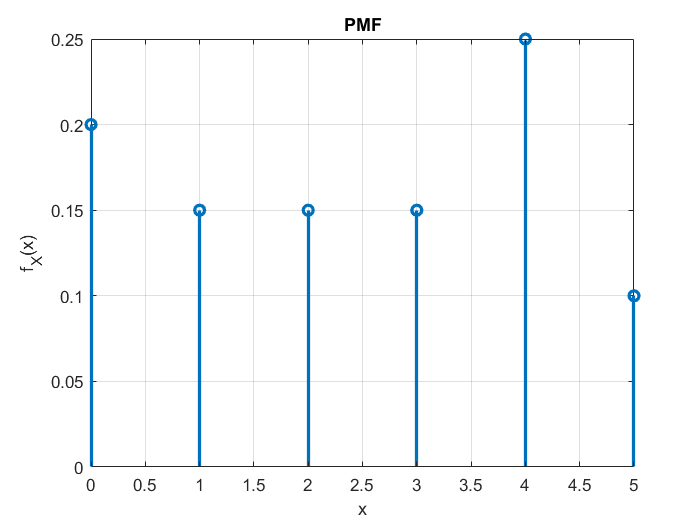

pmf = [0.2 0.15 0.15 0.15 0.25 0.10];

figure()
stem(x,pmf, 'linewidth', 2)
title('PMF'); xlabel('x'); ylabel('f_X(x)');
grid on;

syms x
Pr1 = 0.15; Pr2 = 0.15; Pr3 = 0.15;
Fx(x) = piecewise(x < 0, 0,...
              x < 1, Pr0, ...
              x <= 2, Pr0+Pr1, ...
              x <= 3, Pr0+Pr1+Pr2, ...
              x <= 4, Pr0+Pr1+Pr2+Pr3, ...
              x < 5, Pr0+Pr1+Pr1+Pr1+Pr4, ...
              x >= 5, Pr0+Pr1+Pr2+Pr3+Pr4+Pr5)

$$Fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<0\\ \frac{1}{5} & \text{ if }x<1\\ \frac{7}{20} & \text{ if }x\leq 2\\ \frac{1}{2} & \text{ if }x\leq 3\\ \frac{13}{20} & \text{ if }x\leq 4\\ \frac{9}{10} & \text{ if }x<5\\ 1 & \text{ if }5\leq x \end{array}\right.$$

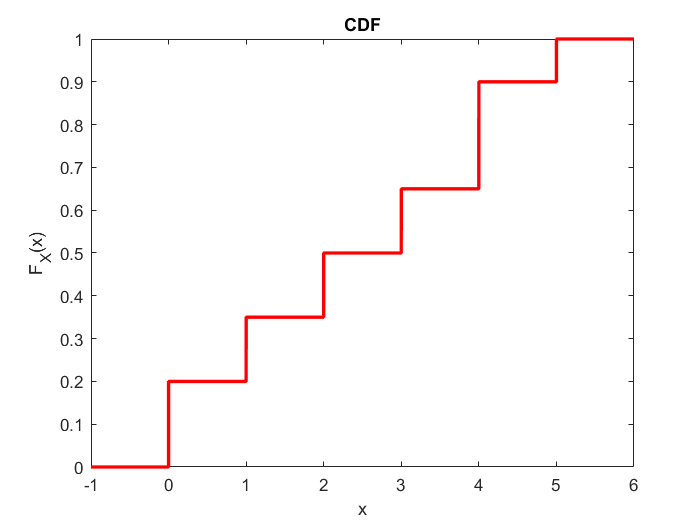

figure()  
fplot(Fx(x),[-1,6],'-r','LineWidth',2)
title('CDF');
xlabel('x');
ylabel('F_X(x)');

c) Bestem middelværdien E[X] af den stokastiske variabel X

Forventningsværdien findes ved:

x = [0:5];
fx = [Pr0,Pr1, Pr2, Pr3, Pr4, Pr5];
EX = sum(fx.*x)

EX =    2.4000e+00


d) Bestem variansen Var(X) af den stokastiske variabel X

EX2 = sum(x.^2.*fx)

EX2 =    8.6000e+00


Variansen findes ved:

variance = EX2 - EX^2

variance =    2.8400e+00


## Opgave 2

format rat

En æggeproducent producere tre typer æg: Buræg, Skrabeæg og Økoæg. Alle æggene sorteres i fire forskellige størrelser: Størrelse 1, 2, 3 og 4. En undersøgelse af æggene fra producenten viser følgende fordeling:

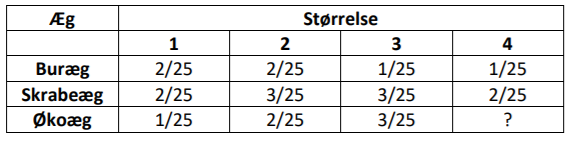

Ved en kontrol udtages tilfældige æg fra producenten. 

a) Hvad er sandsynligheden for, at et tilfældigt æg er et økoæg af størrelse 4?

bur = [2/25 2/25 1/25 1/25];
skrabe = [2/25 3/25 3/25 2/25];
eko = [1/25 2/25 3/25 0];

Pr4eko = 1-sum(bur+skrabe+eko)

Pr4eko =        3/25    


b) Hvad er sandsynligheden for, at et tilfældigt æg er af størrelse 3? 

Pr3 = 1/25 + 3/25 + 3/25

Pr3 =        7/25    


c) Hvad er sandsynligheden for, at et tilfældigt æg er et buræg?

Prbur = 2/25 + 2/25 + 1/25 + 1/25

Prbur =        6/25    


d) Hvis det tilfældige udtagne æg er af størrelse 2, hvad er så sandsynligheden for at det er et skrabeæg?

Pr2skrab = (3/25) / (7/25)

Pr2skrab =        3/7     


## Opgave 3

format

En stokastisk proces er givet ved:

a) Skitser tre realisationer af den stokastiske proces $X\left(t\right)$ i intervallet t = [0; 10].

N = 3; % Antal realisationer
t = [0:10];
mu = 1; variance = 1/4; sigma = sqrt(variance);
%a = normrnd(mu, sigma, [1 N])
a = mu + sigma .* randn(1,N)

a =     0.5802    1.6773    0.4639


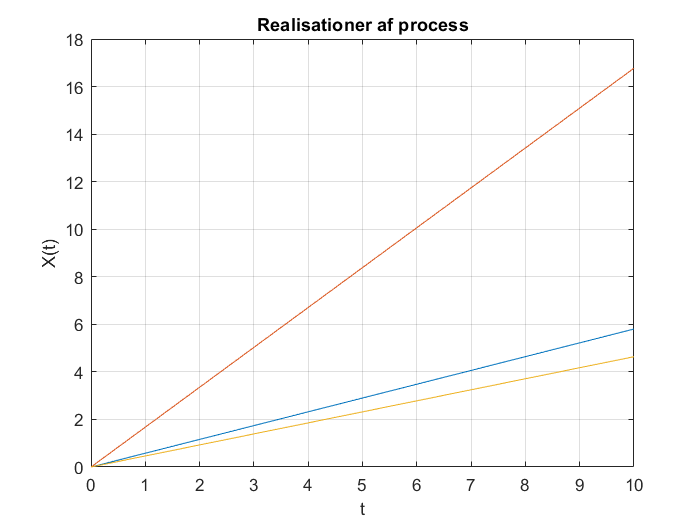

figure()
for i=1:N
    Xt = a(i)*t;
    plot(t, ones(1,length(t)).*Xt);
    hold on
end
grid on
xlabel("t"); ylabel("X(t)"); title("Realisationer af process");

b) Bestem ensemble middelværdi og varians af den stokastiske proces X(t).

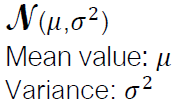

syms t
mu = 1; s2 = 1/4;
EX = mu * t

$$EX = t$$

var_Xt = t^2 * s2

$$var\_Xt = \frac{t^{2}}{4}$$

c) Er den stokastiske proces $X\left(t\right)$ WSS (Wide Sense Stationary)? Er den ergodisk? Svarene skal begrundes.

Da E[X] og Var[X] ikke er konstant uafhængig af t er X ikke WSS.

Da X ikke er WSS er X heller ikke ergodisk.

## Opgave 4

En nyåbnet webshop forventer, at antallet af ordrer vil være poissonfordelt med et gennemsnit på 25 ordrer i timen. Tidspunkterne for de enkelte ordrer antages at være uafhængige af hinanden.

a) Hvad er sandsynligheden for, at der indkommer mere end 30 ordrer på en time? 

Parameterskøn:

xobs = 25; t = 1;
lambda = xobs/t

lambda = 25


$$H_0 :\lambda =\lambda_0$$



$$H_1 :\lambda \not= \lambda_0$$


z = 30; % teststørrelse
pval = 1-poisscdf(z,lambda)

pval = 0.1367

b) Hvad er sandsynligheden for, at der på 4 timer indkommer 80 eller færre ordrer?

lambda4h = 4 * lambda;
z = 80; % teststørrelse
pval = poisscdf(z,lambda4h)'

pval = 0.0226

Over en periode på 24 timer registreres 653 ordrer på webshoppen.

c) Hvad er det estimerede antal ordrer pr. time ud fra denne observation?

t = 24; xobs = 653;
lambda24h = xobs/t

lambda24h = 27.2083

d) Stemmer det observerede antal ordrer overens med antagelsen om et gennemsnit på 25 ordrer i timen med 5% signifikans?

Normal approximation anvendes:

z = (xobs-(t*25))/sqrt(t*25)

z = 2.1637

pval = 2 * (1 - normcdf(abs(z)))

pval = 0.0305

Da p < 0,05 kan hypotesen ikke afvises.

e) Bestem 95% konfidensintervallet for antal ordrer i timen ud fra observationen.

lambda_lower = 1/t * (xobs + 1.96^2/2 - 1.96 * sqrt(xobs + 1.96^2/4))

lambda_lower = 25.1999

lambda_upper = 1/t * (xobs + 1.96^2/2 + 1.96 * sqrt(xobs + 1.96^2/4))

lambda_upper = 29.3768